%  Set options for fminunc
options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 400);

%  Run fminunc to obtain the optimal theta
%  This function will return theta and the cost 
[theta, cost] = fminunc(@(t)(costFunction(t, X, y)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



% Print theta
fprintf('Cost at theta found by fminunc: %f\n', cost);

Cost at theta found by fminunc: 0.203498


disp('theta:');disp(theta);

theta:
  -25.1613
    0.2062
    0.2015



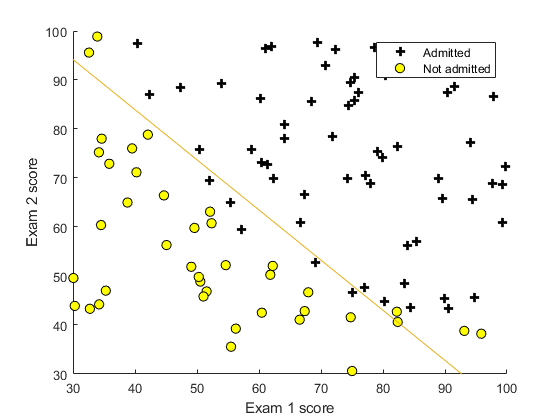


% Plot Boundary
plotDecisionBoundary(theta, X, y);
% Add some labels 
hold on;
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')
% Specified in plot order
legend('Admitted', 'Not admitted')
hold off;


prob = sigmoid([1 45 85] * theta)

prob = 0.7763

fprintf('For a student with scores 45 and 85, we predict an admission probability of %f\n\n', prob);

For a student with scores 45 and 85, we predict an admission probability of 0.776291





p = predict(theta, X)

p = 1

fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100)

Train Accuracy: 60.000000
